close all; clear all; clc;
I = imread('coins.png'); 

% 1. Detectar Bordes con Canny (ajuste de parámetros por defecto o fino)
BW_canny = edge(I, 'canny', [0.1 0.4], 1.5); % Ejemplo de parámetros finos
30

ans = 30

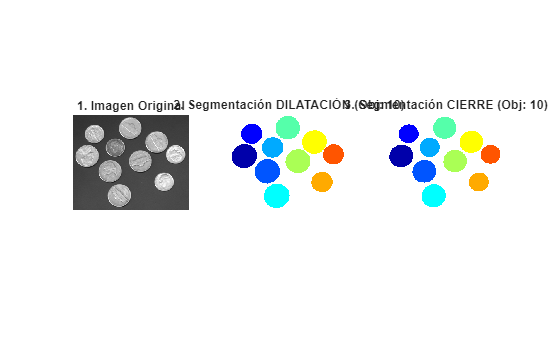

figure('Name','(2) Segmentación Basada en Bordes (Canny)','NumberTitle','off');
subplot(2,3,1); imshow(BW_canny); title('1. Canny Bordes');

% 2. Cerrar Contornos con Dilatación (imdilate)
% Se usa un elemento estructurante (SE) para conectar los bordes fragmentados.
se_dilate = strel('disk', 2); % Disco de radio 2
BW_dilatada = imdilate(BW_canny, se_dilate);
subplot(2,3,2); imshow(BW_dilatada); title('2. Dilatación');

% 3. Rellenar Contornos (Holes)
% Rellena los agujeros (los objetos) dentro de los contornos cerrados.
BW_rellena = imfill(BW_dilatada, 'holes');
subplot(2,3,3); imshow(BW_rellena); title('3. Contornos Rellenos');

% 4. Segmentar y Etiquetar Objetos
% Eliminar el fondo (borde de la imagen) para segmentar solo los objetos internos.
BW_sin_borde = imclearborder(BW_rellena);
[L, num_objetos] = bwlabel(BW_sin_borde);
RGB_seg = label2rgb(L, 'jet', 'w');
subplot(2,3,4); imshow(RGB_seg); title(sprintf('4. Segmentación Canny (Objetos: %d)', num_objetos));

% canny con sin dilatar


I = imread('coins.png'); 
I_gray = I; 

% --- 1. Detectar Bordes con Canny ---
sigma = 1.5;
BW_canny = edge(I_gray, 'canny', [0.1 0.4], sigma); 

% --- 2. Cierre de Contornos (Paso OMITIDO) ---
% La imagen BW_canny pasa directamente al relleno.

% --- 3. Relleno de Contornos (imfill) ---
% Se rellena directamente la imagen de bordes Canny
BW_rellena_sin_dilate = imfill(BW_canny, 'holes');

% --- 4. Segmentación y Etiquetado (bwlabel) ---
BW_sin_borde_sin_dilate = imclearborder(BW_rellena_sin_dilate);
[L_sin_dilate, num_sin_dilate] = bwlabel(BW_sin_borde_sin_dilate);
RGB_seg_sin_dilate = label2rgb(L_sin_dilate, 'jet', 'w');

figure('Name','(2) Segmentación Canny Sin Dilatación','NumberTitle','off');
subplot(2,2,1); imshow(BW_canny); title('1. Bordes Canny');
subplot(2,3,3); imshow(BW_rellena); title('3. Contornos Rellenos con dilatacion');

subplot(2,2,3); imshow(BW_rellena_sin_dilate); title('3. Contornos Rellenos (Fallo)');
subplot(2,2,4); imshow(RGB_seg_sin_dilate); title(sprintf('4. Segmentación Final (Obj: %d)', num_sin_dilate));

%cambiando el strell a cosas mas grandes:

I = imread('coins.png'); 

% 1. Detectar Bordes con Canny (se mantiene fijo)
sigma = 1.5;
BW_canny = edge(I, 'canny', [0.1 0.4], sigma); 

% --- Definición de Elementos Estructurantes (SE) ---
% SE PEQUEÑO: Mantiene la forma, ideal para cerrar huecos mínimos.
se_pequeno = strel('disk', 1); 

% SE MEDIANO: SE de referencia, buen balance.
se_mediano = strel('disk', 3); 

% SE GRANDE: Cierra huecos grandes, riesgo de fusión de objetos.
se_grande = strel('disk', 6); 

% ----------------------------------------------------
% --- Flujo con SE PEQUEÑO (R=1) ---
BW_dilatada_peq = imdilate(BW_canny, se_pequeno);
BW_seg_peq = imfill(BW_dilatada_peq, 'holes');
[~, num_peq] = bwlabel(imclearborder(BW_seg_peq));

% --- Flujo con SE MEDIANO (R=3) ---
BW_dilatada_med = imdilate(BW_canny, se_mediano);
BW_seg_med = imfill(BW_dilatada_med, 'holes');
[~, num_med] = bwlabel(imclearborder(BW_seg_med));

% --- Flujo con SE GRANDE (R=6) ---
BW_dilatada_gde = imdilate(BW_canny, se_grande);
BW_seg_gde = imfill(BW_dilatada_gde, 'holes');
[~, num_gde] = bwlabel(imclearborder(BW_seg_gde));
% ----------------------------------------------------

figure('Name','(2) Comparación Elementos Estructurantes en Dilatación','NumberTitle','off');

subplot(1,3,1); 
imshow(BW_seg_peq); 
title(sprintf('SE Pequeño (R=1). Obj: %d', num_peq));

subplot(1,3,2); 
imshow(BW_seg_med); 
title(sprintf('SE Mediano (R=3). Obj: %d', num_med));

subplot(1,3,3); 
imshow(BW_seg_gde); 
title(sprintf('SE Grande (R=6). Obj: %d', num_gde));

I = imread('coins.png'); 
I_gray = I; 

% Definir el Elemento Estructurante (SE)
se_dilate = strel('disk', 2); 

% ----------------------------------------------------
% --- A. Segmentación Canny (Referencia) ---
sigma = 1.5;
BW_canny = edge(I_gray, 'canny', [0.1 0.4], sigma); 
BW_dilatada_canny = imdilate(BW_canny, se_dilate);
BW_rellena_canny = imfill(BW_dilatada_canny, 'holes');
BW_sin_borde_canny = imclearborder(BW_rellena_canny);
[L_canny, num_canny] = bwlabel(BW_sin_borde_canny);
RGB_seg_canny = label2rgb(L_canny, 'jet', 'w');

% ----------------------------------------------------
% --- B. Segmentación Sobel (Pasos 1 a 5) ---
% 1. Detectar Bordes con Sobel
BW_sobel = edge(I_gray, 'sobel'); 

% 2. Cierre de Contornos (Dilatación)
BW_dilatada_sobel = imdilate(BW_sobel, se_dilate);

% 3. Relleno de Contornos (imfill)
BW_rellena_sobel = imfill(BW_dilatada_sobel, 'holes');

% 4. Segmentación y Etiquetado (bwlabel)
BW_sin_borde_sobel = imclearborder(BW_rellena_sobel);
[L_sobel, num_sobel] = bwlabel(BW_sin_borde_sobel);
RGB_seg_sobel = label2rgb(L_sobel, 'jet', 'w');

% ----------------------------------------------------
% --- Comparación Visual ---
figure('Name','(2) Segmentación Canny vs Sobel','NumberTitle','off');
subplot(1,2,1); imshow(RGB_seg_canny); title(sprintf('Segmentación Canny (Objetos: %d)', num_canny));
subplot(1,2,2); imshow(RGB_seg_sobel); title(sprintf('Segmentación Sobel (Objetos: %d)', num_sobel));

I = imread('coins.png'); 
I_gray = I; 

% --- Definición del SE (Necesario para la comparación anterior, pero no usado en este flujo) ---
se_dilate = strel('disk', 2); 

% ----------------------------------------------------
% --- A. Segmentación Sobel CON Dilatación (Referencia Anterior) ---
BW_sobel_con = edge(I_gray, 'sobel'); 
BW_rellena_con = imfill(imdilate(BW_sobel_con, se_dilate), 'holes');
[~, num_con] = bwlabel(imclearborder(BW_rellena_con));
RGB_seg_con = label2rgb(imclearborder(BW_rellena_con), 'jet', 'w');

% ----------------------------------------------------
% --- B. Segmentación Sobel SIN Dilatación ---
% 1. Detectar Bordes con Sobel
BW_sobel_sin = edge(I_gray, 'sobel'); 

% 2. Cierre de Contornos (Paso OMITIDO) 
% La imagen BW_sobel_sin pasa directamente al relleno.

% 3. Relleno de Contornos (imfill)
BW_rellena_sin = imfill(BW_sobel_sin, 'holes');

% 4. Segmentación y Etiquetado (bwlabel)
BW_sin_borde_sin = imclearborder(BW_rellena_sin);
[~, num_sin] = bwlabel(BW_sin_borde_sin);
RGB_seg_sin = label2rgb(BW_sin_borde_sin, 'jet', 'w');

% ----------------------------------------------------
% --- Comparación Visual ---
figure('Name','(2) Comparación Sobel Con vs Sin Dilatación','NumberTitle','off');
subplot(1,2,1); imshow(RGB_seg_con); title(sprintf('Sobel CON Dilatación (Obj: %d)', num_con));
subplot(1,2,2); imshow(RGB_seg_sin); title(sprintf('Sobel SIN Dilatación (Obj: %d)', num_sin));

I = imread('coins.png'); 
I_gray = I; 

% 1. Detectar Bordes con Sobel (se mantiene fijo)
BW_sobel = edge(I_gray, 'sobel'); 

% --- Definición de Elementos Estructurantes (SE) ---
se_pequeno = strel('disk', 1); 
se_mediano = strel('disk', 3); 
se_grande = strel('disk', 6); 

% ----------------------------------------------------
% --- Flujo con SE PEQUEÑO (R=1) ---
BW_dilatada_peq = imdilate(BW_sobel, se_pequeno);
BW_seg_peq = imfill(BW_dilatada_peq, 'holes');
BW_sin_borde_peq = imclearborder(BW_seg_peq); % Eliminar borde antes de etiquetar
[L_peq, num_peq] = bwlabel(BW_sin_borde_peq);
RGB_seg_peq = label2rgb(L_peq, 'jet', 'w'); % ¡Generar pseudo-color!

% --- Flujo con SE MEDIANO (R=3) ---
BW_dilatada_med = imdilate(BW_sobel, se_mediano);
BW_seg_med = imfill(BW_dilatada_med, 'holes');
BW_sin_borde_med = imclearborder(BW_seg_med);
[L_med, num_med] = bwlabel(BW_sin_borde_med);
RGB_seg_med = label2rgb(L_med, 'jet', 'w'); % ¡Generar pseudo-color!

% --- Flujo con SE GRANDE (R=6) ---
BW_dilatada_gde = imdilate(BW_sobel, se_grande);
BW_seg_gde = imfill(BW_dilatada_gde, 'holes');
BW_sin_borde_gde = imclearborder(BW_seg_gde);
[L_gde, num_gde] = bwlabel(BW_sin_borde_gde);
RGB_seg_gde = label2rgb(L_gde, 'jet', 'w'); % ¡Generar pseudo-color!

% ----------------------------------------------------

figure('Name','(2) Comparación SE en Dilatación (Sobel) [Pseudo-Color]','NumberTitle','off');

subplot(1,3,1); 
imshow(RGB_seg_peq); % Mostrar la imagen RGB
title(sprintf('Sobel + R=1 (Obj: %d)', num_peq));

subplot(1,3,2); 
imshow(RGB_seg_med); % Mostrar la imagen RGB
title(sprintf('Sobel + R=3 (Obj: %d)', num_med));

subplot(1,3,3); 
imshow(RGB_seg_gde); % Mostrar la imagen RGB
title(sprintf('Sobel + R=6 (Obj: %d)', num_gde));


close all; clear all; clc;
I = imread('coins.png'); 
I_gray = I; % Imagen original en gris

% 1. Detección de Bordes con Canny (se mantiene fijo)
BW_canny = edge(I_gray, 'canny', [0.1 0.4], 1.5); 
se_morph = strel('disk', 2); 

% ----------------------------------------------------
% --- A. Segmentación con DILATACIÓN (imdilate) ---
BW_dilatada = imdilate(BW_canny, se_morph);
BW_rellena_dilatada = imfill(BW_dilatada, 'holes');
BW_sin_borde_dilatada = imclearborder(BW_rellena_dilatada);
[L_dilatada, num_dilatada] = bwlabel(BW_sin_borde_dilatada);
% Resultado Pseudo-Color
RGB_seg_dilatada = label2rgb(L_dilatada, 'jet', 'w');

% ----------------------------------------------------
% --- B. Segmentación con CIERRE (imclose) ---
BW_cierre = imclose(BW_canny, se_morph);
BW_rellena_cierre = imfill(BW_cierre, 'holes');
BW_sin_borde_cierre = imclearborder(BW_rellena_cierre);
[L_cierre, num_cierre] = bwlabel(BW_sin_borde_cierre);
% Resultado Pseudo-Color
RGB_seg_cierre = label2rgb(L_cierre, 'jet', 'w');

% ----------------------------------------------------
% --- Visualización para Comparación Directa ---

figure('Name','(2) Comparación Segmentación vs Original','NumberTitle','off');

% 1. Imagen Original
subplot(1,3,1); 
imshow(I_gray); 
title('1. Imagen Original');

% 2. Resultado con Dilatación
subplot(1,3,2); 
imshow(RGB_seg_dilatada); 
title(sprintf('2. Segmentación DILATACIÓN (Obj: %d)', num_dilatada));

% 3. Resultado con Cierre
subplot(1,3,3); 
imshow(RGB_seg_cierre); 
title(sprintf('3. Segmentación CIERRE (Obj: %d)', num_cierre));